clc; clear; close all;

DATA = xlsread('Five_times_Kinematics_HT_Query_final.xlsx');

MF = DATA(:,2);
X = DATA(:,5:end)';
[n, p] = size(X');
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 77 dimensiones.



mu = mean(X);             % 1 x p
S = cov(X);               % p x p
invS = inv(S);

% Calcular distancias de Mahalanobis observadas
D2 = zeros(n, 1);
for i = 1:n
    diff = X(i, :) - mu;
    D2(i) = diff * invS * diff';
end
D2_sorted = sort(D2);

% Cuantiles teóricos de chi-cuadrado con p grados de libertad
chi2_quant = chi2inv(((1:n)' - 0.5) / n, p);

% -----------------------------
% Bootstrap no paramétrico
% -----------------------------
B = 500;
alpha = 0.01;
lower_p = alpha/2;
upper_p = 1 - alpha/2;

D2_boot = zeros(n, B);
for b = 1:B
    idx = randi(n, n, 1);       % re-muestreo con reemplazo
    Xb = X(idx, :);

    mub = mean(Xb);
    Sb = cov(Xb);
    invSb = pinv(Sb);

    D2b = zeros(n,1);
    for i = 1:n
        diff_b = Xb(i,:) - mub;
        D2b(i) = diff_b * invSb * diff_b';
    end
    D2_boot(:,b) = sort(D2b);
end

% Calcular bandas de confianza
lower_env = quantile(D2_boot, lower_p, 2);
upper_env = quantile(D2_boot, upper_p, 2);

% -----------------------------
% Ajuste lineal: pendiente y R²
% -----------------------------
coeffs = polyfit(chi2_quant, D2_sorted, 1);
y_fit = polyval(coeffs, chi2_quant);
R2 = corr(chi2_quant, D2_sorted)^2;

% Mostrar resultados numéricos
fprintf('\n--- Resultados de ajuste lineal ---\n');


--- Resultados de ajuste lineal ---


fprintf('Pendiente: %.4f\n', coeffs(1));

Pendiente: 1.1184


fprintf('R²: %.4f\n', R2);

R²: 0.9397


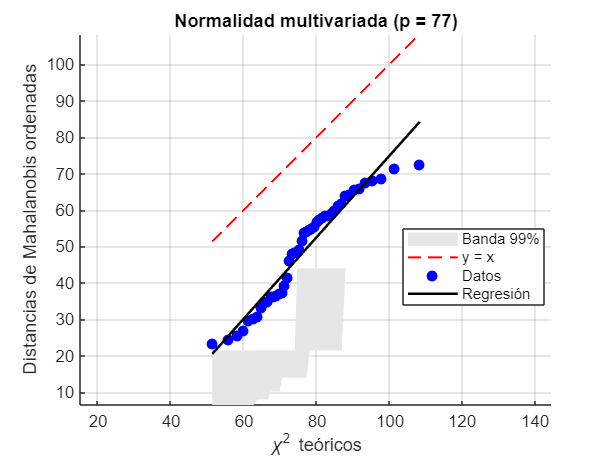


% -----------------------------
% Gráfico Chi-square plot
% -----------------------------
figure;
hold on;
fill([chi2_quant; flipud(chi2_quant)], ...
     [lower_env; flipud(upper_env)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none');
plot(chi2_quant, chi2_quant, 'r--', 'LineWidth', 1.2); % identidad
plot(chi2_quant, D2_sorted, 'bo', 'MarkerFaceColor','b');
plot(chi2_quant, y_fit, 'k-', 'LineWidth', 1.5);       % regresión

xlabel('\chi^2 teóricos');
ylabel('Distancias de Mahalanobis ordenadas');
title(['Normalidad multivariada (p = ', num2str(p), ')']);
legend('Banda 99%', 'y = x', 'Datos', 'Regresión', 'Location', 'best');
axis equal;
grid on;